%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                                         %
%                   LAB 1 - ASEN 2004                     %
%                 Glider Wing Analysis                    %
%                                                         %
%                                                         %
%        This script conducts parameter analysis          %
%      for six different geometric parameters and         %
%           outputs those that meet all of the            %
%               glider lab requirements.                  %
%                                                         %
%                  Created: 02/21/2021                    %
%               Last Modified: 02/27/2021                 %
%                                                         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tic

## Set Environment

clear
clc
close all

## Declare and Define the Glider Variables

global wConv W_payload W_ballast b d L Re e0org C_fe h rho mu e_b ...
    e_c_r e_c_t e_lambda v_c_r v_c_t v_lambda ...
    v_b payload_h payload_w payload_l x_le ...
    ballast_h ballast_w ballast_l v_flow ...
    reynolds_crit dataAct x_payload_f x_ballast_f Gamma

% Given Variables
Re = 160000;                % Glider Reynold's Number [dimensionless]
e0org = 0.601;              % Glider Oswald's Efficiency 
C_fe = 0.003;               % Civil Transport Skin Friction Coefficient
h = 7;                      % Glider launch altitude [m]
rho = 1.0581;               % Air density STD ATM for Boulder [kg/m^3]
mu = 1.74*(10^-5);          % Viscosity [kg/m s]
W_payload = 1.5696;         % GoPro Camera Weight [N]
wConv = 0.295*9.81;         % Weight Conversion Constant [N / m^2]

## Set User Variables

n = 10; % number of iterations for testing

% FUSELAGE DIMENSIONS
d = 0.075;                              % Glider Fuselage Width [m]
L = 0.75;                               % Glider Fuselage Length [m]

% MAIN WING
b = 1;                                  % Glider Main Wing Span [m]
%w_c_r = 0.071;                         % Glider Main Wing Root Chord [m]
%w_c_t = 0.071;                         % Glider Main Wing Tip Chord  [m]
w_c_r = linspace(0.05,0.25,n);          
w_c_t = w_c_r;
w_lambda = w_c_t./w_c_r;                % Glider Main Wing Taper Ratio [dimensionless]

x_le = 0.356944;                        % Location of the main wing leading edge in x direction [m]
%x_le = 0.36;

% HORIZONTAL STABILIZER
e_b = 0.25;                             % Glider Elevator Span [m]
%e_c_r = 0.05325;                       % Glider Elevator Root Chord [m]
%e_c_t = 0.026625;                      % Glider Elevator Tip Chord  [m]
e_c_r = 0.138889;
e_c_t = 0.5.*e_c_r;
e_lambda = e_c_t./e_c_r;                % Glider Elevator Taper Ratio [dimensionless]

% VERTICAL STABILIZER
v_b = 0.15;                             % Glider Vertical Stabilizer Span [m]
%v_c_r = 0.071;                         % Glider Vertical Stabilizer Root Chord [m]
%v_c_t = 0.05325;                       % Glider Vertical Stabilizer Tip Chord  [m]
v_c_r = 0.205556;
v_c_t = 0.5*v_c_r;
v_lambda = v_c_t./v_c_r;                % Glider Vertical Stabilizer Taper Ratio [dimensionless]

% PAYLOAD
payload_h = 0.039;                      % Payload Height [m]
payload_w = 0.0593;                     % Payload Width [m]
payload_l = 0.0698;                     % Payload Length [m]
x_payload_f = 0.5;     % The location of the payload front face 
                                        %   with respect to the nose cone tip [m]
% BALLAST
W_ballast = 3;                          % Glider Ballast Weight [N]
ballast_h = 0.03;                       % Ballast Height [m]
ballast_w = 0.03;                       % Ballast Width [m]
ballast_l = 0.03;                       % Ballast Length [m]
x_ballast_f = 0.25;          % The location of the ballast front face 
                                        %   with respect to the nose cone tip [m]
% REYNOLD'S
v_flow = 12;                            % Velocity of Airflow [m/s] - Currently the max of vel. requirment
reynolds_crit = 5*(10^5);               % Critical Reynold's Number for a flat plate

% DIHEDRAL ANGLE
Gamma = 11;

## Appendix Two - Flat Plate Approximation Tables

[AOA C_l C_d C_M]

dataAct = [-15 -0.6  0.2  0.09;
         -14 -0.6  0.2  0.09; 
         -13 -0.7  0.2  0.09;
         -12 -0.8  0.19 0.085;
         -11 -0.8  0.18 0.08;
         -10 -0.75 0.14 0.07;
         -9  -0.85 0.12 0.055;
         -8  -0.8  0.1  0.04;
         -7  -0.7  0.08 0.03;
         -6  -0.6  0.06 0;
         -5  -0.5  0.04 -0.01;
         -4  -0.4  0.02 -0.005;
         -3  -0.3  0.01 0;
         -2  -0.2  0.005 0;
         -1  -0.1  0.005 0;
         0   0     0     0;
         1   0.1   0     0;
         2   0.2   0.005 0;
         3   0.3   0.01  0;
         4   0.4   0.02  0;
         5   0.45  0.04  0;
         6   0.6   0.06  0;
         7   0.7   0.08  -0.01;
         8   0.8   0.12  -0.03;
         9   0.8   0.13  -0.06;
         10  0.8   0.14  -0.08;
         11  0.8   0.16  -0.1;
         12  0.8   0.18  -0.1;
         13  0.8   0.19  -0.1;
         14  0.74  0.21  -0.1;
         15  0.74  0.22  -0.1;
         16  0.74  0.24  -0.1;
         17  0.73  0.25  -0.1;
         18  0.73  0.26  -0.1;
         19  0.7   0.28  -0.1;
         20  0.7   0.3   -0.1;];

## Preallocate vectors for max range, endurance, and velocities

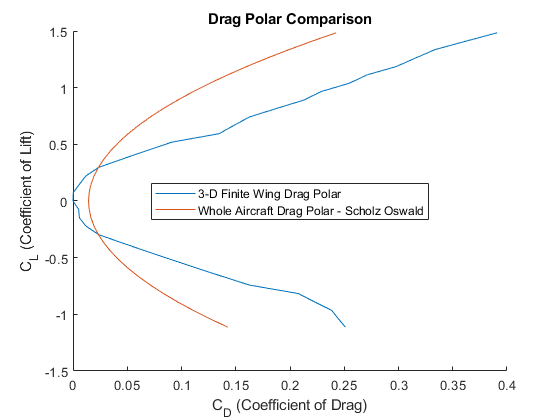

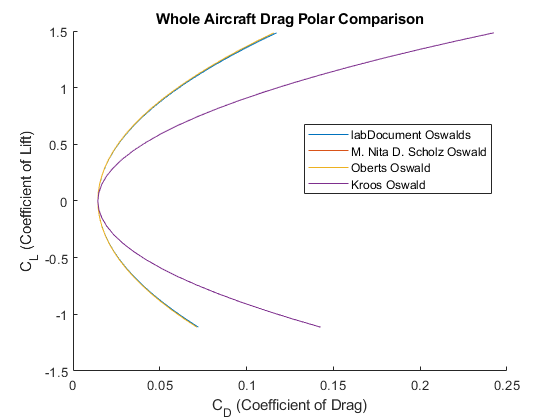

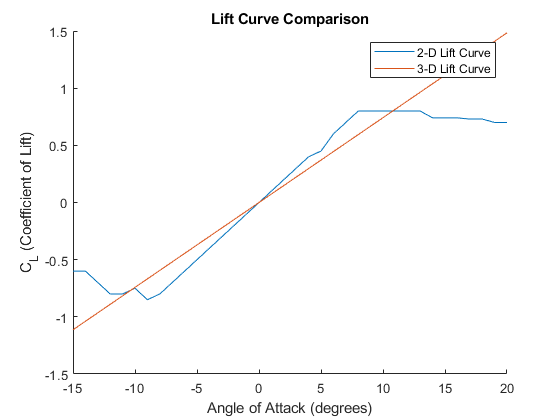

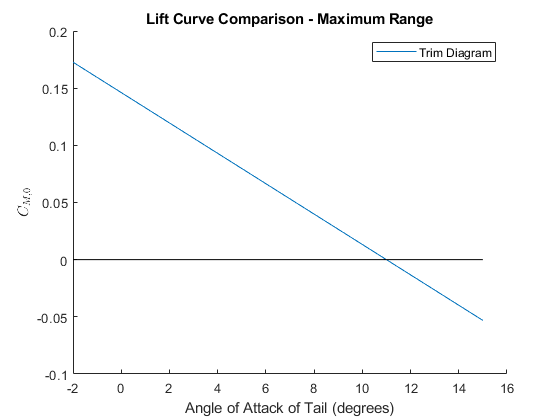

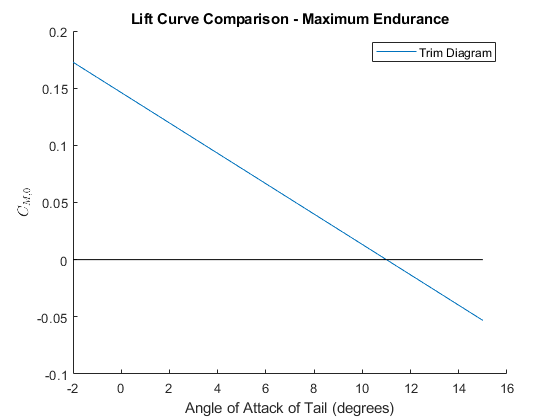

Results = 5×8 table
               Glide LDMax    Glide C_L Max    Glide C_L for Min Power    Glide Max Range Velocity (m/s)    Glide Max Endurance Velocity (m/s)    Glide AoA (deg)    Max Glide Range (m)    Max Glide Endurance (s)
               ___________    _____________    _______________________    ______________________________    __________________________________    _______________    ___________________    _______________________

    Kroos        12.986          0.37105               0.64393                        16.388                              12.445                      4.4034               90.902                   6.2337         
    Lab Doc      19.295          0.51

max_range = zeros(1,n);
max_endur = zeros(1,n);
max_range_v = zeros(1,n);
max_endur_v = zeros(1,n);
wing_loading = zeros(1,n);
bool = zeros(1,n);
V_H = zeros(1,n);
V_v = zeros(1,n);
B = zeros(1,n);
i_t_range = zeros(1,n);
i_t_endur = zeros(1,n);
S_ref = zeros(1,n);
S_wet = zeros(1,n);
W_glider = zeros(1,n);
AR = zeros(1,n);
x_cg = zeros(1,n);
C_D_0 = zeros(1,n);


for i=1:n
    [max_range(i),max_endur(i),max_range_v(i),max_endur_v(i),...
        wing_loading(i),bool(i),V_H(i),V_v(i),B(i),i_t_range(i),...
        i_t_endur(i),S_wet(i),S_ref(i),W_glider(i),AR(i),...
        x_cg(i),C_D_0(i)] = ...
        planformanalysis(w_c_r(i),w_lambda(i));
end

## Results and pulling out best configuration

maxreqs = max(bool);

%idx = find(bool==maxreqs);
%
idx = find(bool==maxreqs);
%[~,idx] = min(abs(B(idx1)-5));
num = length(idx);
%[~,bestB] = min(abs(B(mostreqs)-5));
% [I1,I2,I3,I4,I5,I6] = ind2sub(size(bool),mostreqs(bestB));
for i=1:num
fprintf('Wing chord length = %f m\n',w_c_r(idx(i)));
fprintf('Elev chord length = %f m\n',e_c_r);
fprintf('Vert chord length = %f m\n',v_c_r);
fprintf('Leading edge of wing = %f m from nose tip\n',x_le);
fprintf('Payload location = %f m from nose tip\n',x_payload_f);
fprintf('Ballast location = %f m from nose tip\n',x_ballast_f);
fprintf('Dihedral angle = %f deg\n',Gamma);

fprintf('\n... produces the following: \n\n');

fprintf('Max range: %f m \n',max_range(idx(i)));
fprintf('Max endurance: %f s \n',max_endur(idx(i)));
fprintf('Max range velocity: %f m/s \n',max_range_v(idx(i)));
fprintf('Max endurance velocity: %f m/s\n',max_endur_v(idx(i)));
fprintf('V_H: %f\n',V_H(idx(i)));
fprintf('V_v: %f\n',V_v(idx(i)));
fprintf('B: %f\n',B(idx(i)));
fprintf('Incidence angle (max range): %f deg\n',i_t_range(idx(i)));
fprintf('Incidence angle (max endurance): %f deg\n',i_t_endur(idx(i)));
fprintf('Reference planform area = %f m^2\n',S_ref(idx(i)));
fprintf('Total wetted surface area = %f m^2\n',S_wet(idx(i)));
fprintf('Glider weight = %f N\n',W_glider(idx(i)));
fprintf('Aspect ratio = %f \n',AR(idx(i)));
fprintf('\nCoefficient of zero lift = %f \n',C_D_0(idx(i)));
fprintf('Total weight = %f N \n',W_glider(idx(i))+W_ballast+W_payload);
fprintf('Center of gravity: %f m from leading edge of wing\n',x_cg(idx(i)));
fprintf('      = %fc\n',x_cg(idx(i))/w_c_r(idx(i)));
fprintf('Wing loading (W_TO/S_ref): %f N/m^2\n',(W_glider(idx(i))+W_ballast+W_payload)/S_ref(idx(i)));
fprintf('Cost: $%f\n\n',W_glider(idx(i))*1000/9.81);
end

Wing chord length = 0.116667 m


Elev chord length = 0.138889 m


Vert chord length = 0.205556 m


Leading edge of wing = 0.356944 m from nose tip


Payload location = 0.500000 m from nose tip


Ballast location = 0.250000 m from nose tip


Dihedral angle = 11.000000 deg



... produces the following: 



Max range: 113.252271 m 


Max endurance: 8.893509 s 


Max range velocity: 14.901286 m/s 


Max endurance velocity: 11.317886 m/s


V_H: 0.575185


V_v: 0.041787


B: 4.999849


Incidence angle (max range): -14.679275 deg


Incidence angle (max endurance): -15.292803 deg


Reference planform area = 0.116667 m^2


Total wetted surface area = 0.556667 m^2


Glider weight = 1.610966 N


Aspect ratio = 8.571429 



Coefficient of zero lift = 0.014314 


Total weight = 6.180566 N 


Center of gravity: 0.016654 m from leading edge of wing


      = 0.142752c


Wing loading (W_TO/S_ref): 52.976279 N/m^2


Cost: $164.216708



## PLOT

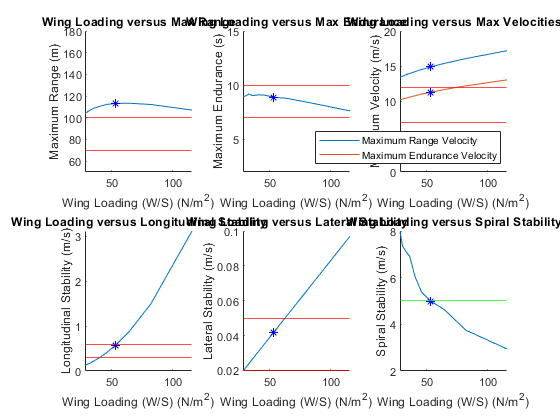

figure(6);
subplot(2,3,1)
hold on
plot(wing_loading,max_range);
plot(wing_loading(idx),max_range(idx),'*b');
yline(100,'r');
yline(70,'r');
ylim([50,180]);
%xline(56.86848,'g');
xlabel('Wing Loading (W/S) (N/m^2)');
ylabel('Maximum Range (m)');
%legend("Calculated Wing Loading","Threshold","Upper Limit",'Location','northwest')
title("Wing Loading versus Max Range")
hold off

subplot(2,3,2)
hold on
plot(wing_loading,max_endur);
plot(wing_loading(idx),max_endur(idx),'*b');
yline(10,'r');
yline(7,'r');
ylim([2,15]);
%xline(56.86848,'g');
xlabel('Wing Loading (W/S) (N/m^2)');
ylabel('Maximum Endurance (s)');
%legend("Calculated Wing Loading","Threshold","Upper Limit",'Location','northwest')
title("Wing Loading versus Max Endurance")
hold off

subplot(2,3,3)
hold on
plot(wing_loading,max_range_v,wing_loading,max_endur_v);
plot(wing_loading(idx),max_range_v(idx),'*b');
plot(wing_loading(idx),max_endur_v(idx),'*b');
yline(12,'r');
yline(7,'r');
ylim([0,20]);
%xline(56.86848,'g');
xlabel('Wing Loading (W/S) (N/m^2)');
ylabel('Maximum Velocity (m/s)');
legend("Maximum Range Velocity","Maximum Endurance Velocity",'Location','southeast')
title("Wing Loading versus Max Velocities")
hold off

subplot(2,3,4)
hold on
plot(wing_loading,V_H);
plot(wing_loading(idx),V_H(idx),'*b');
yline(0.6,'r');
yline(0.3,'r');
xlabel('Wing Loading (W/S) (N/m^2)');
ylabel('Longitudinal Stability (m/s)');
%legend("Calculated Wing Loading","Threshold","Upper Limit",'Location','northwest')
title("Wing Loading versus Longitudinal Stability")
hold off

subplot(2,3,5)
hold on
plot(wing_loading,V_v);
plot(wing_loading(idx),V_v(idx),'*b');
yline(0.02,'r');
yline(0.05,'r');
xlabel('Wing Loading (W/S) (N/m^2)');
ylabel('Lateral Stability (m/s)');
%legend("Calculated Wing Loading","Threshold","Upper Limit",'Location','northwest')
title("Wing Loading versus Lateral Stability")
hold off

subplot(2,3,6)
hold on
plot(wing_loading,B);
plot(wing_loading(idx),B(idx),'*b');
yline(5,'g');
xlabel('Wing Loading (W/S) (N/m^2)');
ylabel('Spiral Stability (m/s)');
%legend("Calculated Wing Loading","Threshold","Upper Limit",'Location','northwest')
title("Wing Loading versus Spiral Stability")
hold off

## Functions

% finiteWingLift
%
% Function that calculates the 3D finite wing 3D lift coefficient and 3D wing
% drag polar
%
% @param data   The table data that includes the AOA, C_l, and the C_d in
%                   that order.
% @param vars   Needed variables on a per aircraft process like Aspect ratio
%                   and oswald's number
% @param aoa_one The lowest AOA to evaluate at
% @param aoa_two The highest AOA to evaluate at
%

function [a, C_L,C_D_wing] = finiteWingLift(data,vars,aoa_one,aoa_two)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    
    % Get the slope of the linear portion of the 2D lift curve from airfoil data
    linearFit = polyfit(data(data(data(:,1)<aoa_two,1)>aoa_one,1),data(data(data(:,1)<aoa_two,1)>aoa_one,2),1);
    
    % Set the slope of 2D airfoil curve as a_0 according to convention
    a_0 = linearFit(1);
    
    % Define the Span Efficiency factor
    e = 0.9;
    
    % Define a the lift curve slope
    a = a_0/(1+((57.3*a_0)/(pi*e*AR)));
    
    % Get the AOA where the C_L equal 0
    %alpha_aoa_0 = interp1(data(:,2),data(:,1),0,'linear','extrap'); % FOR ANYTHING ELSE
    alpha_aoa_0 = data(find(data(:,2)==0),1); % FOR FLAT PLATE
    
    % Calculate C_L for all AOA
    C_L = a*(data(:,1)-alpha_aoa_0);
    
    % Calculate C_D_wing
    C_D_wing = data(:,3) + (C_L.^2)./(pi*e*AR);
end

% wholeAircraftDragPolar
%
% Function that calculates the whole aircraft drag polar
%
% @param C_L        The calculated C_L values for a specific aircraft
% @param C_D_Wing   The calculated C_D_wing values for a specific aircraft
% @param e_0        The Oswald's Efficiency number for a specific model
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function [C_D,C_D_0] = wholeAircraftDragPolar(C_L, C_D_wing, e_0, vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    S_wet = vars(4);    % Wet Planform Area
    S_ref = vars(5);    % Reference Planfrom Area
    C_f_e = vars(6);    % Coefficient of Skin Friction
    
    % Calculate K1
    k_1 = 1/(pi*e_0*AR);
    
    % Calculate C_D_min
    C_D_min = C_f_e * (S_wet/S_ref);
    
    % Calculate C_L_minD
    xmin = find(C_D_wing==min(C_D_wing));
    C_L_minD = C_L(xmin);
    
    % Calculate the Whole Aircraft Drag Polar
    C_D = C_D_min + (k_1*((C_L-C_L_minD).^2));
    
    % Calculate C_D_0
    C_D_0 = C_D_min + (k_1*(C_L_minD^2));
end

## Oswald's Efficiency Calculation Functions

% labDocument
%
% Function that Oswald's number using the Lab Document method equation 12
%
% @param vars       Needed variables on a per aircraft process like Aspect Ratio
%                       and oswald's number
%
function e = labDocument(vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    
    % Calculate Oswald's factor
    e = (1.78*(1-(0.045*(AR^0.68)))) - 0.64;
end

% MNita_DScholz
%
% Function that Oswald's number using M. Nita D. Scholz method
%
% @param C_D        The Coefficient of Drag for Finite Wing
% @param e          The Span Efficieny Factor
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function e = MNita_DScholz(C_D, e, vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    d = vars(7);        % Fuselage Diameter
    b = vars(8);        % Aircraft Wing Span
    K_e_m = 1;          % 1 because aircrafts are subsonic
    
    % Define k_e_f
    k_e_f = 1 - (2*((d/b)^2));
    
    % Find C_D_0
    C_D_0 = C_D(6); % AOA of 0 degrees
    
    % Define Q
    Q = 1 / (e*k_e_f);
    
    % Define P
    P = 0.38*C_D_0;
    
    % Calculate Oswald's factor
    e = K_e_m/(Q+(P*pi*AR));
end

% oberts
%
% Function that Oswald's number using Obert's method
%
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function e = oberts(vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio

    % Calculate Oswald's factor
    e = 1/(1.05+(0.007*pi*AR));
end

% kroos
%
% Function that Oswald's number using Kroo's method
%
% @param C_D        The Coefficient of Drag for Finite Wing
% @param e          The Span Efficieny Factor
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function e = kroos(C_D, e, vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    d = vars(7);        % Fuselage Diameter
    b = vars(8);        % Aircraft Wing Span
    K = 0.38;           % WTF is K?
    
    % Define u
    u = e;
    
    % Define S
    s = 1 - (2*((d/b)^2));
    
    % Find C_D_0
    C_D_0 = C_D(6); % AOA of 0 degrees
    
    % Define P
    P = K*C_D_0;
    
    % Calculate Oswald's Factor
    e = 1/((1/(u*s))+(P*pi*AR));
end

## Performance Calculations

glide

% Calculates L/Dmax, ranges and velocities for max endurance and max range
% glide

function [LDmax,C_L_max,C_L_endur,V_range,V_endur,theta_range,theta_endur,R_max,endurance] = glide(h,C_D,C_L,e0,AR,rho,W,S,C_D_0)
% max endurance: at 3CD0 = kCL^2
% max range: at CD0 = kCL^2

    % define k
    k = 1/(AR*pi*e0);
    C_L_range = sqrt(C_D_0/k);
    C_L_endur = sqrt(3*C_D_0/k);
    [LDmax,idx] = max(C_L./C_D);
    C_L_max = C_L(idx);
    [~,idx2] = min(abs(C_L-C_L_endur));
    R_max = h*(C_L(idx)/C_D(idx));
    R_endur = h*(C_L(idx2)/C_D(idx2));
    
    % calculate glide angle
    theta_range = atan(h/R_max);
    theta_endur = atan(h/R_endur);
    
    % calculate velocities for max range and max endurance
    V_range = sqrt((2*cos(theta_range)*W)/(rho*C_L_range*S));
    V_endur = sqrt((2*cos(theta_endur)*W)/(rho*C_L_endur*S));
    sink_rate = V_endur*(sin(theta_endur));
    endurance = h/sink_rate;
    
    theta_range = rad2deg(theta_range);
    theta_endur = rad2deg(theta_endur);
end



function [max_range,max_endur,max_range_v,max_endur_v,...
    wing_loading,bool,V_H,V_v,B,i_t1,i_t2,S_wet,S_ref,W_glider,AR,x_cg,C_D_0] = ...
    planformanalysis(w_c_r,w_lambda)


global wConv W_payload W_ballast b d L Re e0org C_fe h rho mu e_b ...
    e_c_r e_c_t e_lambda v_c_r v_c_t v_lambda ...
    v_b payload_h payload_w payload_l x_le ...
    ballast_h ballast_w ballast_l v_flow ...
    reynolds_crit dataAct x_payload_f x_ballast_f Gamma

## Define Surface Areas

S_ref = (b/2)*w_c_r*(1+w_lambda);       % Glider Reference Planform Area [m^2]
%S_ref = linspace(0.05,0.22,30);
S_vert = (v_b/2)*v_c_r*(1+v_lambda);    % Glider Vertical Planform Area [m^2]
S_elev = (e_b/2)*e_c_r*(1+e_lambda);    % Glider Horizontal Stabilizer Planform Area [m^2]
S_fuselage = (4*L*d);                   % Glider Fuselage Wet Surface Area

% Define Glider Variables
AR = (b^2)/(S_ref);                                        % Glider Aspect Ratio [dimensionless]
S_wet = S_fuselage + (2*S_ref) + (2*S_elev) + (2*S_vert);  % Glider Wet Planform Area [m^2]
W_glider = wConv*S_wet;                                % Glider Weight [N]
W = W_glider + W_payload + W_ballast;                       % Total Glider Weight [N]
W_wing = wConv*S_ref;                                  % Wing Weight [N]

x_v_le = L - v_c_r;                     % Location of the vertical stab leading edge in the x direction [m]

% Calculate Mean Aerodynamic Chord for main wing
c_bar = (2/3)*w_c_r*((1+w_lambda+(w_lambda^2))/(1+w_lambda));

% Calculate Mean Aerodynamic Chord for horizontal stab.
c_e_bar = (2/3)*e_c_r*((1+e_lambda+(e_lambda^2))/(1+e_lambda));

% Calculate Mean Aerodynamic Chord for vertical stab.
c_v_bar = (2/3)*v_c_r*((1+v_lambda+(v_lambda^2))/(1+v_lambda));

% Calculate Reynold's Number for Tapered Main Wing
reynolds_c_bar = (rho*(v_flow)*c_bar)/mu;

% Calculate x critical (the point where flow goes from laminar to turbulent)
x_cr = (reynolds_crit*mu)/(rho*v_flow);
x_c = x_cr/w_c_r;

% Create the Variable Array for the Tempest
vars = [AR, Re, e0org, S_wet, S_ref, C_fe, d, b];

## Calculate all the center of gravities in the x direction

% cg_fuselage - the x location of the fuselage's center of gravity with
% respect to its nose cone tip
cg_fuselage = (L/2);

% x_cg_fuselage - the x location of the fuselage's center of gravity with
% respect to the leading edge of the main wing
x_cg_fuselage = cg_fuselage - x_le;

% x_ac_w - the x location of the main wing mean aerodynamic center from the 
% leading edge of the main wing
x_ac_w = 0.25*c_bar;

% h_ac_w - the x location of the main wing mean aerodynamic center
% normalized with respect to the mean aerodynamic chord
h_ac_w = x_ac_w / c_bar;

% x_cg_wing - the x location of the main wing's center of gravity with
% respect to it's leading edge
x_cg_wing = 0.5*c_bar;

% cg_vertical - the x location of the vertical stab. center of gravity with respect to it's
% leading edge
cg_vertical = 0.5*c_v_bar;

% x_cg_vertical - the x location of the vertical stab. center of gravity
% with respect to the leading edge of the main wing
x_cg_vertical = (x_v_le + cg_vertical) - x_le;

% x_ac_v - the x location of the vertical stab mean aerodynamic center from the 
% leading edge of the main wing
x_ac_v = (x_v_le + (0.25*c_v_bar)) - x_le;

% cg_horizontal - the x location of the horizontal stab. center of gravity with respect to
% it's leading edge
cg_horizontal = 0.5*c_e_bar;

% x_cg_horizontal - the x location of the horizontal stab. center of
% gravity with respect to the main wing leading edge
x_e_le = x_v_le+(v_c_r - v_c_t);           % The start of the horizontal stab leading edge [m] 
                                           % assuming T-tail where leading edge starts at leading
                                           % edge of vertical stab tip
x_cg_horizontal = (x_e_le + cg_horizontal) - x_le;

% x_ac_h - the x location of the horizontal stab mean aerodynamic center from the 
% leading edge of the main wing
x_ac_h = (x_e_le + (0.25*c_e_bar)) - x_le;

% cg_payload - the x location of the payload's center of gravity with
% respect to it's front face
cg_payload  = (payload_l/2);

% x_cg_payload - the x location of the payload's center of gravity with
% respect to the main win leading edge
x_cg_payload = (x_payload_f + cg_payload) - x_le;

% cg_ballast - the x location of the ballast's center of gravity with
% respect to it's front face
cg_ballast  = (ballast_l/2);

% x_cg_ballast - the x location of the ballast's center of gravity with
% respect to the main win leading edge
x_cg_ballast = (x_ballast_f + cg_ballast) - x_le;

% Declare and Define remaining weights
W_fuselage = wConv*S_fuselage;
W_horz_stab = wConv*2*S_elev;
W_vert_stab = wConv*2*S_vert;

% x_cg - the location of the aircraft cg at an x distance from the leading
% edge of the main wing (The sum of all the cg's in the x direction divided by their total weight)
x_cg = ((W_fuselage*x_cg_fuselage) + ...
        (W_horz_stab*x_cg_horizontal) + ...
        (W_vert_stab*x_cg_vertical) + ...
        (W_payload*x_cg_payload) + ...
        (W_ballast*x_cg_ballast)) / W;
% h_cg - the location of the aircraft cg normalized with respect to the
% mean aerodynamic chord
h_cg = x_cg / c_bar;

## Calculations

% Calculate the C_L and C_D 
[a_w, C_L,C_D_w] = finiteWingLift(dataAct,vars,0,6);

% Calculate the Whole Drag Polar using labDocument method
eLabDocument = labDocument(vars);
[C_D_labDocument,C_D_0_labDocument] = wholeAircraftDragPolar(C_L, C_D_w, eLabDocument, vars);

% Calculate the Whole Drag Polar using MNita_DScholz method
eMNita_DScholz = MNita_DScholz(C_D_w, 0.9, vars);
[C_D_MNita_DScholz,C_D_0_MNita_DScholz] = wholeAircraftDragPolar(C_L, C_D_w, eMNita_DScholz, vars);

% Calculate the Whole Drag Polar using Oberts method
eOberts = oberts(vars);
[C_D_Oberts,C_D_0_Oberts] = wholeAircraftDragPolar(C_L, C_D_w, eOberts, vars);

% Calculate the Whole Drag Polar using Kroo's method
eKroos = kroos(C_D_w, 0.9, vars);
[C_D_Kroos,C_D_0_Kroos] = wholeAircraftDragPolar(C_L, C_D_w, eKroos, vars);

% Combine all Oswald's factors and C_Ds in one array for performance calcs
e0 = [eKroos,eLabDocument,eMNita_DScholz,eOberts];
C_D = [C_D_Kroos,C_D_labDocument,C_D_MNita_DScholz,C_D_Oberts];
C_D_0 = mean([C_D_0_Oberts,C_D_0_labDocument,C_D_0_MNita_DScholz,C_D_0_Kroos]);

## Performace Flight Conditions Calculations

% Define empty arrays for glide LDmaxes
Glide_LDMax = zeros(1,4);

% Define empty arrays for max glide ranges, endurances, angles and velocities
Glide_Range_V = zeros(1,4);
Glide_Endur_V = zeros(1,4);
Glide_Theta = zeros(1,4);
Glide_Range = zeros(1,4);
Glide_Endurance = zeros(1,4);
Glide_Theta_Endur = zeros(1,4);

% Performance calculations for each Oswald's using calculated data
for i=1:4
   [Glide_LDMax(i),Glide_C_L_Max(i),Glide_C_L_Pmin(i),...
       Glide_Range_V(i),Glide_Endur_V(i),Glide_Theta(i),...
       Glide_Theta_Endur(i),Glide_Range(i),Glide_Endurance(i)] = ...
       glide(h,C_D(:,i),C_L,e0(i),...
       AR,rho,W,S_ref,C_D_0); 
end

max_range = mean(Glide_Range);
max_endur = mean(Glide_Endurance);
max_range_v = mean(Glide_Range_V);
max_endur_v = mean(Glide_Endur_V);

wing_loading = W/S_ref;

## Lateral Directional Stability

% Lateral Stability Equation
V_v = (S_vert*(x_ac_v - x_cg)) / (S_ref * b);

% must have 11 degree dihedral to be approximately neutral spiral
B = ((x_ac_v - x_cg)./b) .* (Gamma./mean(Glide_C_L_Max));

## Longitudinal Stability

% Longitudinal Stability Equation
V_H = (S_elev*(x_ac_h - x_cg)) / (S_ref * w_c_r);

## Trimmed flight

1 - refers to maximum range trim 2 - refers to maximum endurance trim

C_m_ac_w = dataAct(:,4);
AoA = dataAct(:,1);

C_L_ht1 = abs((C_m_ac_w + mean(Glide_C_L_Max)*((x_cg-x_ac_w)/w_c_r))./V_H);
C_L_ht2 = abs((C_m_ac_w + mean(Glide_C_L_Pmin)*((x_cg-x_ac_w)/w_c_r))./V_H);

alpha_w1 = -mean(Glide_Theta);
alpha_w2 = -mean(Glide_Theta_Endur);

aoa1 = find(AoA==0);
aoa2 = find(AoA==10);

a_01 = (C_L_ht1(aoa2)-C_L_ht1(aoa1))/(AoA(aoa2)-AoA(aoa1));
a_02 = (C_L_ht2(aoa2)-C_L_ht2(aoa1))/(AoA(aoa2)-AoA(aoa1));

a_t1 = a_01/(1+(57.3*a_01)/(pi*mean(e0)*AR));
a_t2 = a_02/(1+(57.3*a_02)/(pi*mean(e0)*AR));

C_L_req1 = a_t1*alpha_w1;
C_L_req2 = a_t2*alpha_w2;

[~,trim1] = min(C_L_req1-C_L_ht1);
[~,trim2] = min(C_L_req2-C_L_ht2);

%[~,trim] = min(abs(a-C_L_ht));
alpha_tail1 = AoA(trim1);
alpha_tail2 = AoA(trim2);

i_t1 = alpha_w1 - alpha_tail1;
i_t2 = alpha_w2 - alpha_tail2;

% Longitudinal Trim Diagrams
d_epsilion_d_alpha = 0.3;

% Stable when partial_C_m_cg < 0
partial_C_m_cg1 = a_w*((h_cg - h_ac_w)-((a_t1/a_w)*V_H*(1-d_epsilion_d_alpha))); 
partial_C_m_cg2 = a_w*((h_cg - h_ac_w)-((a_t2/a_w)*V_H*(1-d_epsilion_d_alpha)));

alpha_e1 = alpha_tail1;
alpha_e2 = alpha_tail2;

% Stable when C_M_0 > 0
C_M_01 = (-1)*(alpha_e1*partial_C_m_cg1);
C_M_02 = (-1)*(alpha_e2*partial_C_m_cg2);


trim_slope1 = [partial_C_m_cg1 C_M_01];
trim_slope2 = [partial_C_m_cg2 C_M_02];

alpha_tail_range = [-2 15];
trimDiag1 = polyval(trim_slope1, alpha_tail_range);
trimDiag2 = polyval(trim_slope2, alpha_tail_range);

% Neutral Point
h_NP1 = h_ac_w + (V_H*(a_t1/a_w)*(1-d_epsilion_d_alpha));
h_NP2 = h_ac_w + (V_H*(a_t2/a_w)*(1-d_epsilion_d_alpha));

% Static Margin
SM1 = h_NP1 - h_cg;
SM2 = h_NP2 - h_cg;

## Check Requirements

bool = 0;
if max_range > 70 && max_range < 100 
    bool = bool+1;
end
if max_endur > 7 && max_endur < 10 
    bool = bool+1;
end
if max_range_v > 7 && max_range_v < 12 
    bool = bool+1;
end
if max_endur_v > 7 && max_endur_v < 12 
    bool = bool+1;
end
if V_v > 0.02 && V_v < 0.05
    bool = bool+1;
end
if V_H > 0.3 && V_H < 0.6
    bool = bool+1;
end
if partial_C_m_cg1 < 0 && C_M_01 > 0
    bool = bool+1;
end
if partial_C_m_cg2 < 0 && C_M_02 > 0
    bool = bool+1;
end
if B > 4.8 && B < 5.2     
    bool = bool+1;
end
if x_cg < w_c_r && x_cg > 0
    bool = bool+1;
end
if abs(i_t1) > 8 && abs(i_t1) < 10
    bool = bool+1;
end
if abs(i_t2) > 8 && abs(i_t2) < 10
    bool = bool+1;
end

if bool==8
figure;
hold on
%plot(dataAct(:,3), dataAct(:,2));
plot(C_D_w,C_L);
plot(C_D_MNita_DScholz,C_L);
title('Drag Polar Comparison');
ylabel('C_L (Coefficient of Lift)');
xlabel('C_D (Coefficient of Drag)');
legend('3-D Finite Wing Drag Polar','Whole Aircraft Drag Polar - Scholz Oswald','Location','best');
hold off

figure;
hold on
plot(C_D_labDocument,C_L);
plot(C_D_MNita_DScholz,C_L);
plot(C_D_Oberts,C_L);
plot(C_D_Kroos,C_L);
%plot(dataAct(:,3),dataAct(:,2));
title('Whole Aircraft Drag Polar Comparison');
xlabel('C_D (Coefficient of Drag)');
ylabel('C_L (Coefficient of Lift)');
legend('labDocument Oswalds', ...
       'M. Nita D. Scholz Oswald', ...
       'Oberts Oswald', ...
       'Kroos Oswald', 'Location', 'best');
%    'Glider CFD Drag Polar'
hold off

figure;
hold on
plot(dataAct(:,1),dataAct(:,2));
plot(dataAct(:,1),C_L);
title('Lift Curve Comparison');
xlabel('Angle of Attack (degrees)');
ylabel('C_L (Coefficient of Lift)');
legend('2-D Lift Curve','3-D Lift Curve');
hold off

% Plot Longitudinal Trim Diagrams
figure;
hold on
plot(alpha_tail_range, trimDiag1)
plot(alpha_tail_range, zeros(length(alpha_tail_range),1),'k')
title('Lift Curve Comparison - Maximum Range');
xlabel('Angle of Attack of Tail (degrees)');
ylabel({'\textbf{$C_{M,0}$}'},'Interpreter','latex');
legend('Trim Diagram');
hold off

figure;
hold on
plot(alpha_tail_range, trimDiag2)
plot(alpha_tail_range, zeros(length(alpha_tail_range),1),'k')
title('Lift Curve Comparison - Maximum Endurance');
xlabel('Angle of Attack of Tail (degrees)');
ylabel({'\textbf{$C_{M,0}$}'},'Interpreter','latex');
legend('Trim Diagram');
hold off


Results = table([Glide_LDMax';mean(Glide_LDMax)],...
    [Glide_C_L_Max';mean(Glide_C_L_Max)],...
    [Glide_C_L_Pmin';mean(Glide_C_L_Pmin)],...
    [Glide_Range_V';mean(Glide_Range_V)],...
    [Glide_Endur_V';mean(Glide_Endur_V)],...
    [Glide_Theta';mean(Glide_Theta)],...
    [Glide_Range';mean(Glide_Range)],...
    [Glide_Endurance';mean(Glide_Endurance)],...
    'RowNames',{'Kroos','Lab Doc','Scholz','Oberts','Mean'},...
    'VariableNames',{'Glide LDMax','Glide C_L Max',...
    'Glide C_L for Min Power','Glide Max Range Velocity (m/s)',...
    'Glide Max Endurance Velocity (m/s)',...
    'Glide AoA (deg)','Max Glide Range (m)','Max Glide Endurance (s)'})
end
end